%% Step 7: 平日/週末の比較分析
% 目的：「時系列相関が顧客層の違いを反映する」という仮説を検証する。
%       平日と週末で顧客層が異なると仮定し、相関パターンの差異を分析する。
%
% 入力: step6_results.mat
% 出力: step7_results.mat

clear; clc; close all;

%% 1. 設定
set(0, 'DefaultAxesFontName', 'MS Gothic');
set(0, 'DefaultTextFontName', 'MS Gothic');
set(0, 'DefaultAxesFontSize', 10);

baseDir = '/MATLAB Drive/DAC25';
dataDir = fullfile(baseDir, '01_Data');
outputDir = fullfile(baseDir, '03_Visualization');
if ~exist(outputDir, 'dir'), mkdir(outputDir); end


%% 2. Step6の結果をロード
fprintf('\nStep6の結果をロード中...\n');


Step6の結果をロード中...



step6Path = fullfile(dataDir, 'step6_results.mat');
if ~exist(step6Path, 'file')
    error('step6_results.mat が見つかりません。Step6を先に実行してください。');
end

load(step6Path);
fprintf('完了\n');

完了



salesMatrix = step6Results.salesMatrix;
uniqueDates = step6Results.uniqueDates;
uniqueCategories = step6Results.uniqueCategories;
nCategories = size(salesMatrix, 1);


%% 3. 平日/週末の分離
% 曜日: 1=日, 2=月, 3=火, 4=水, 5=木, 6=金, 7=土
weekdayVec = weekday(uniqueDates);

% 平日 (月-金: 2-6) と週末 (土日: 1,7)
isWeekday = ismember(weekdayVec, 2:6);
isWeekend = ismember(weekdayVec, [1, 7]);

nWeekday = sum(isWeekday);
nWeekend = sum(isWeekend);

fprintf('\n分析対象:\n');


分析対象:


fprintf('  カテゴリ数: %d\n', nCategories);

  カテゴリ数: 34


fprintf('  平日: %d日\n', nWeekday);

  平日: 262日


fprintf('  週末: %d日\n', nWeekend);

  週末: 104日


%% 4. 平日/週末それぞれの相関行列を計算
fprintf('\n相関行列を計算中...\n');


相関行列を計算中...



salesMatrix_weekday = salesMatrix(:, isWeekday);
corrMatrix_weekday = corrcoef(salesMatrix_weekday');

salesMatrix_weekend = salesMatrix(:, isWeekend);
corrMatrix_weekend = corrcoef(salesMatrix_weekend');

fprintf('完了\n');

完了


%% 5. 結果の比較と評価
fprintf('\n--- 結果の評価 ---\n');


--- 結果の評価 ---



% 上三角行列のみを抽出
upper_tri_mask = triu(true(nCategories), 1);
vec_weekday = corrMatrix_weekday(upper_tri_mask);
vec_weekend = corrMatrix_weekend(upper_tri_mask);

% 行列間の類似度（ベクトル間相関）
matrix_similarity = corr(vec_weekday, vec_weekend);

% 差分
corr_diff = corrMatrix_weekend - corrMatrix_weekday;
vec_diff = corr_diff(upper_tri_mask);

fprintf('\n========== 結果サマリ ==========\n');


========== 結果サマリ ==========


fprintf('平日-週末の相関行列類似度: r = %.3f\n', matrix_similarity);

平日-週末の相関行列類似度: r = 0.737


fprintf('差分の平均: %.3f\n', mean(vec_diff));

差分の平均: -0.008


fprintf('差分の標準偏差: %.3f\n', std(vec_diff));

差分の標準偏差: 0.142


fprintf('================================\n');


% インデックス取得
[row, col] = find(upper_tri_mask);

% 週末で相関が強くなるペア
[sorted_desc, idx_desc] = sort(vec_diff, 'descend');
fprintf('\n--- 週末で相関が強くなるペア (TOP 5) ---\n');


--- 週末で相関が強くなるペア (TOP 5) ---


for i = 1:min(5, length(sorted_desc))
    r_idx = row(idx_desc(i));
    c_idx = col(idx_desc(i));
    fprintf('%d. カテゴリ%2d vs カテゴリ%2d (平日:%.2f -> 週末:%.2f, 差:+%.2f)\n', ...
        i, uniqueCategories(r_idx), uniqueCategories(c_idx), ...
        corrMatrix_weekday(r_idx, c_idx), corrMatrix_weekend(r_idx, c_idx), ...
        sorted_desc(i));
end

1. カテゴリ 5 vs カテゴリ33 (平日:-0.19 -> 週末:0.37, 差:+0.56)
2. カテゴリ 3 vs カテゴリ33 (平日:0.01 -> 週末:0.55, 差:+0.54)
3. カテゴリ31 vs カテゴリ33 (平日:-0.02 -> 週末:0.51, 差:+0.53)
4. カテゴリ 8 vs カテゴリ33 (平日:-0.27 -> 週末:0.26, 差:+0.53)
5. カテゴリ17 vs カテゴリ33 (平日:0.05 -> 週末:0.54, 差:+0.49)



% 平日で相関が強くなるペア
[sorted_asc, idx_asc] = sort(vec_diff, 'ascend');
fprintf('\n--- 平日で相関が強くなるペア (TOP 5) ---\n');


--- 平日で相関が強くなるペア (TOP 5) ---


for i = 1:min(5, length(sorted_asc))
    r_idx = row(idx_asc(i));
    c_idx = col(idx_asc(i));
    fprintf('%d. カテゴリ%2d vs カテゴリ%2d (平日:%.2f -> 週末:%.2f, 差:%.2f)\n', ...
        i, uniqueCategories(r_idx), uniqueCategories(c_idx), ...
        corrMatrix_weekday(r_idx, c_idx), corrMatrix_weekend(r_idx, c_idx), ...
        sorted_asc(i));
end

1. カテゴリ25 vs カテゴリ32 (平日:0.29 -> 週末:-0.16, 差:-0.45)
2. カテゴリ 2 vs カテゴリ34 (平日:0.11 -> 週末:-0.28, 差:-0.39)
3. カテゴリ16 vs カテゴリ34 (平日:0.41 -> 週末:0.03, 差:-0.38)
4. カテゴリ25 vs カテゴリ30 (平日:0.33 -> 週末:-0.04, 差:-0.37)
5. カテゴリ15 vs カテゴリ34 (平日:0.25 -> 週末:-0.10, 差:-0.35)


%% 6. 可視化
fprintf('\n結果を可視化中...\n');


結果を可視化中...


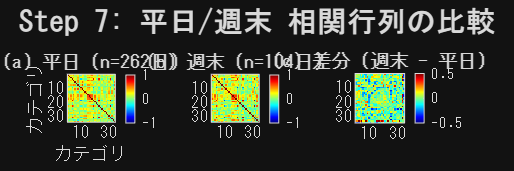


fig1 = figure('Name', '平日/週末比較', 'Position', [50 50 1800 600]);

% (a) 平日の相関行列
subplot(1, 3, 1);
imagesc(corrMatrix_weekday);
title(sprintf('(a) 平日 (n=%d日)', nWeekday));
axis square; colorbar; colormap('jet'); caxis([-1 1]);
xlabel('カテゴリ'); ylabel('カテゴリ');

% (b) 週末の相関行列
subplot(1, 3, 2);
imagesc(corrMatrix_weekend);
title(sprintf('(b) 週末 (n=%d日)', nWeekend));
axis square; colorbar; colormap('jet'); caxis([-1 1]);

% (c) 差分
subplot(1, 3, 3);
imagesc(corr_diff);
title('(c) 差分 (週末 - 平日)');
axis square; colorbar; colormap('jet'); caxis([-0.5 0.5]);

sgtitle('Step 7: 平日/週末 相関行列の比較', 'FontSize', 14, 'FontWeight', 'bold');

saveas(fig1, fullfile(outputDir, 'Step7_Corr_Matrices.png'));

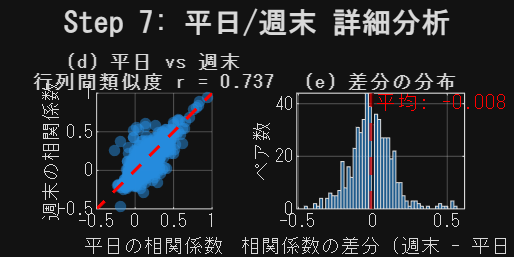


% 追加の可視化
fig2 = figure('Name', '平日/週末比較2', 'Position', [100 100 1200 600]);

% (d) 散布図
subplot(1, 2, 1);
scatter(vec_weekday, vec_weekend, 30, 'filled', 'MarkerFaceAlpha', 0.5);
hold on;
plot([-1 1], [-1 1], 'r--', 'LineWidth', 1.5);
xlabel('平日の相関係数');
ylabel('週末の相関係数');
title(sprintf('(d) 平日 vs 週末\n行列間類似度 r = %.3f', matrix_similarity));
axis square; grid on;
xlim([-0.5 1]); ylim([-0.5 1]);

% (e) 差分の分布
subplot(1, 2, 2);
histogram(vec_diff, 50);
xlabel('相関係数の差分 (週末 - 平日)');
ylabel('ペア数');
title('(e) 差分の分布');
xline(mean(vec_diff), 'r--', 'LineWidth', 2);
xline(0, 'k-', 'LineWidth', 1);
grid on;
text(mean(vec_diff)+0.02, max(ylim)*0.9, sprintf('平均: %.3f', mean(vec_diff)), 'Color', 'r');

sgtitle('Step 7: 平日/週末 詳細分析', 'FontSize', 14, 'FontWeight', 'bold');

saveas(fig2, fullfile(outputDir, 'Step7_Diff_Analysis.png'));

fprintf('図を保存しました\n');

図を保存しました


%% 7. 結果の保存
step7Results.corrMatrix_weekday = corrMatrix_weekday;
step7Results.corrMatrix_weekend = corrMatrix_weekend;
step7Results.matrix_similarity = matrix_similarity;
step7Results.vec_diff = vec_diff;
step7Results.nWeekday = nWeekday;
step7Results.nWeekend = nWeekend;
step7Results.mean_diff = mean(vec_diff);
step7Results.std_diff = std(vec_diff);

save(fullfile(dataDir, 'step7_results.mat'), 'step7Results');
fprintf('\n結果を保存: %s\n', fullfile(dataDir, 'step7_results.mat'));


結果を保存: /MATLAB Drive/DAC25/01_Data/step7_results.mat



fprintf('\n========================================\n');

fprintf('=== Step 7 完了 ===\n');

=== Step 7 完了 ===


fprintf('========================================\n');

% Step8実行前の確認箇所
load(fullfile(dataDir, 'step3_results.mat'));
load(fullfile(dataDir, 'step4_results.mat'));
disp('=== step3Results ===');

=== step3Results ===


disp(fieldnames(step3Results));

    {'storeList'        }
    {'patternSimilarity'}
    {'storeTotalSales'  }
    {'storeValidFlags'  }
    {'storeCorrMatrices'}
    {'typicalStore'     }
    {'atypicalStore'    }
    {'validSimilarities'}



disp('=== step4Results ===');

=== step4Results ===


disp(fieldnames(step4Results));

    {'storeMetrics'   }
    {'storeSize'      }
    {'salesThresholds'}



disp(fieldnames(step4Results.storeMetrics));

    {'storeCode'        }
    {'totalSales'       }
    {'patternSimilarity'}
    {'avgDailySales'    }
    {'nCategories'      }
    {'nActiveDays'      }
    {'topCategoryShare' }
    {'avgCustomers'     }
    {'salesPerCustomer' }
    {'size'             }
    {'storeName'        }

